clc
clear all

combined_wav_files = zeros(960000, 6);

[combined_wav_files(:,1),fs] = audioread('testData\IRs_valerio\pos_0_speaker_1\ir_pos_0_speaker_1_mic1.wav');
[combined_wav_files(:,2),fs] = audioread('testData\IRs_valerio\pos_0_speaker_1\ir_pos_0_speaker_1_mic2.wav');
[combined_wav_files(:,3),fs] = audioread('testData\IRs_valerio\pos_0_speaker_1\ir_pos_0_speaker_1_mic3.wav');
[combined_wav_files(:,4),fs] = audioread('testData\IRs_valerio\pos_0_speaker_1\ir_pos_0_speaker_1_mic4.wav');
[combined_wav_files(:,5),fs] = audioread('testData\IRs_valerio\pos_0_speaker_1\ir_pos_0_speaker_1_mic5.wav');
[combined_wav_files(:,6),fs] = audioread('testData\IRs_valerio\pos_0_speaker_1\ir_pos_0_speaker_1_mic6.wav');

a = createSDMStruct('DefaultArray','GRASVI50','fs',fs,'winLen',15);

User-defined SDM Settings are used :
           fs: 192000
            c: 345
       winLen: 15
    parFrames: 8192
    showArray: 0
      micLocs: [6×3 double]



DOA{1} = SDMbf(combined_wav_files, a);

Started SDM processing
Ended SDM processing in 0.067615 seconds.



% Here we are using the pressure in the b-format as the estimate for the
% pressure in the center of the array
P{1} = combined_wav_files(:,1);

v = createVisualizationStruct('DefaultRoom','LargeRoom',...
    'name','Pori, Concert Hall','fs',fs,'t',[2 5 10 20 50 100 200 2000]);

createVisualizationStruct : User-defined visualization settings are used :
              fs: 192000
           plane: 'lateral'
             DOI: 'forward'
       plotStyle: 'line'
            name: 'Pori, Concert Hall'
             res: 1
               t: [2 5 10 20 50 100 200 2000]
          colors: [8×3 double]
       dBSpacing: 6
      DOASpacing: 30
      dBDynamics: 45
       linewidth: [1 1 1 1 1 1 1 1]
        showGrid: 1
    smoothMethod: 'average'
       smoothRes: 3



Started visualization of parameters.


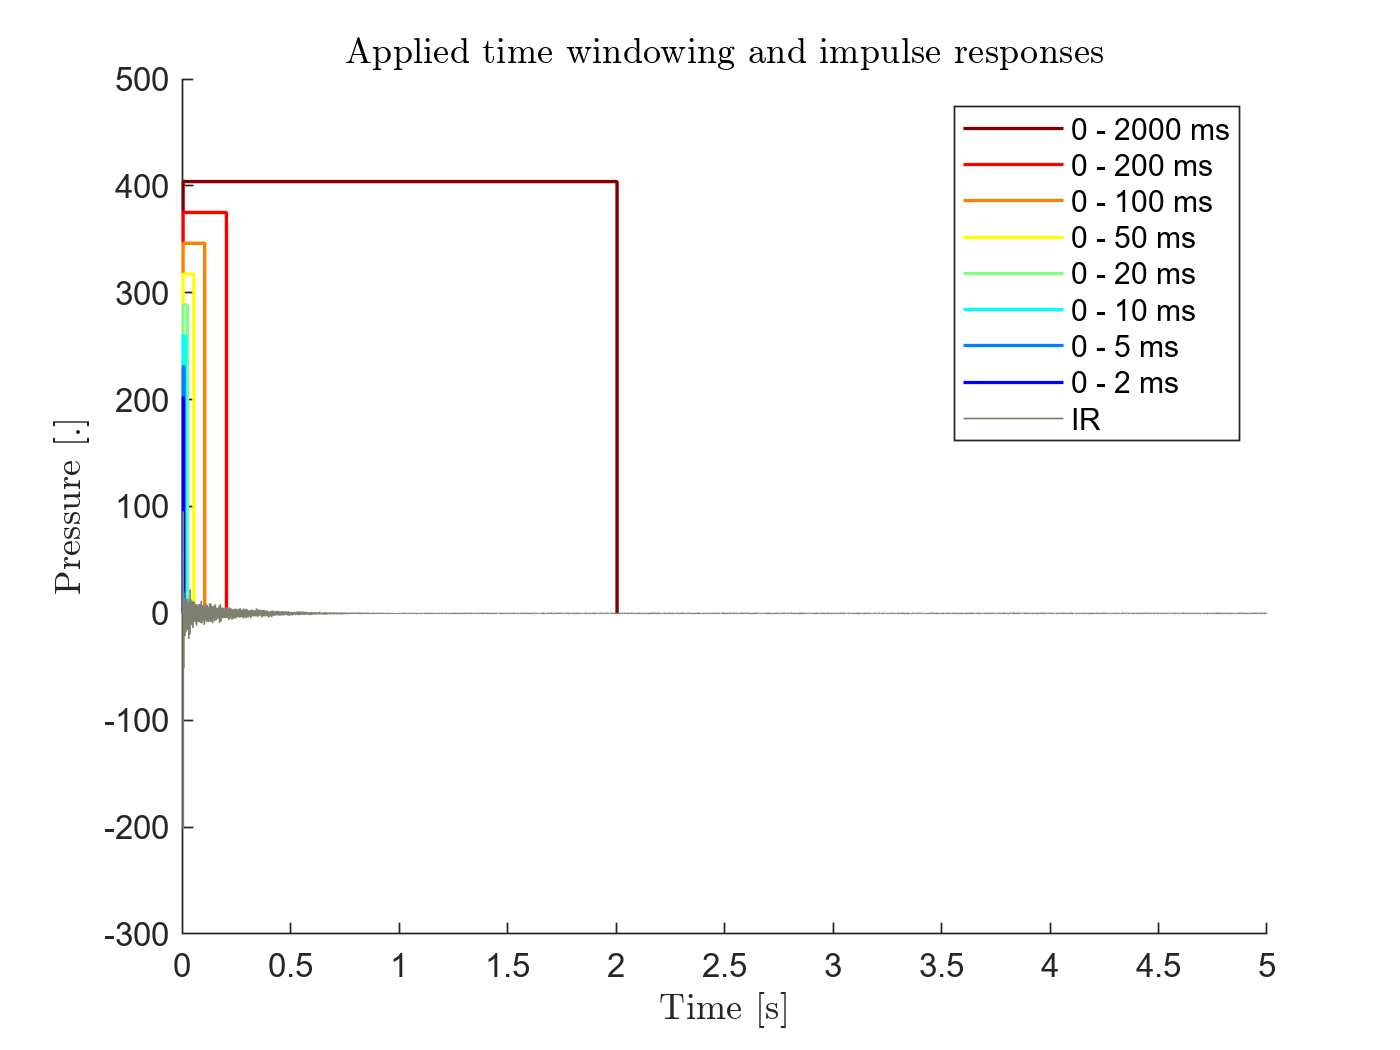

Ended visualization of parameters in 0.29884 seconds.


% For visualization purposes, set the text interpreter to latex
set(0,'DefaultTextInterpreter','latex')
parameterVisualization(P, v);

Started time-frequency visualization.


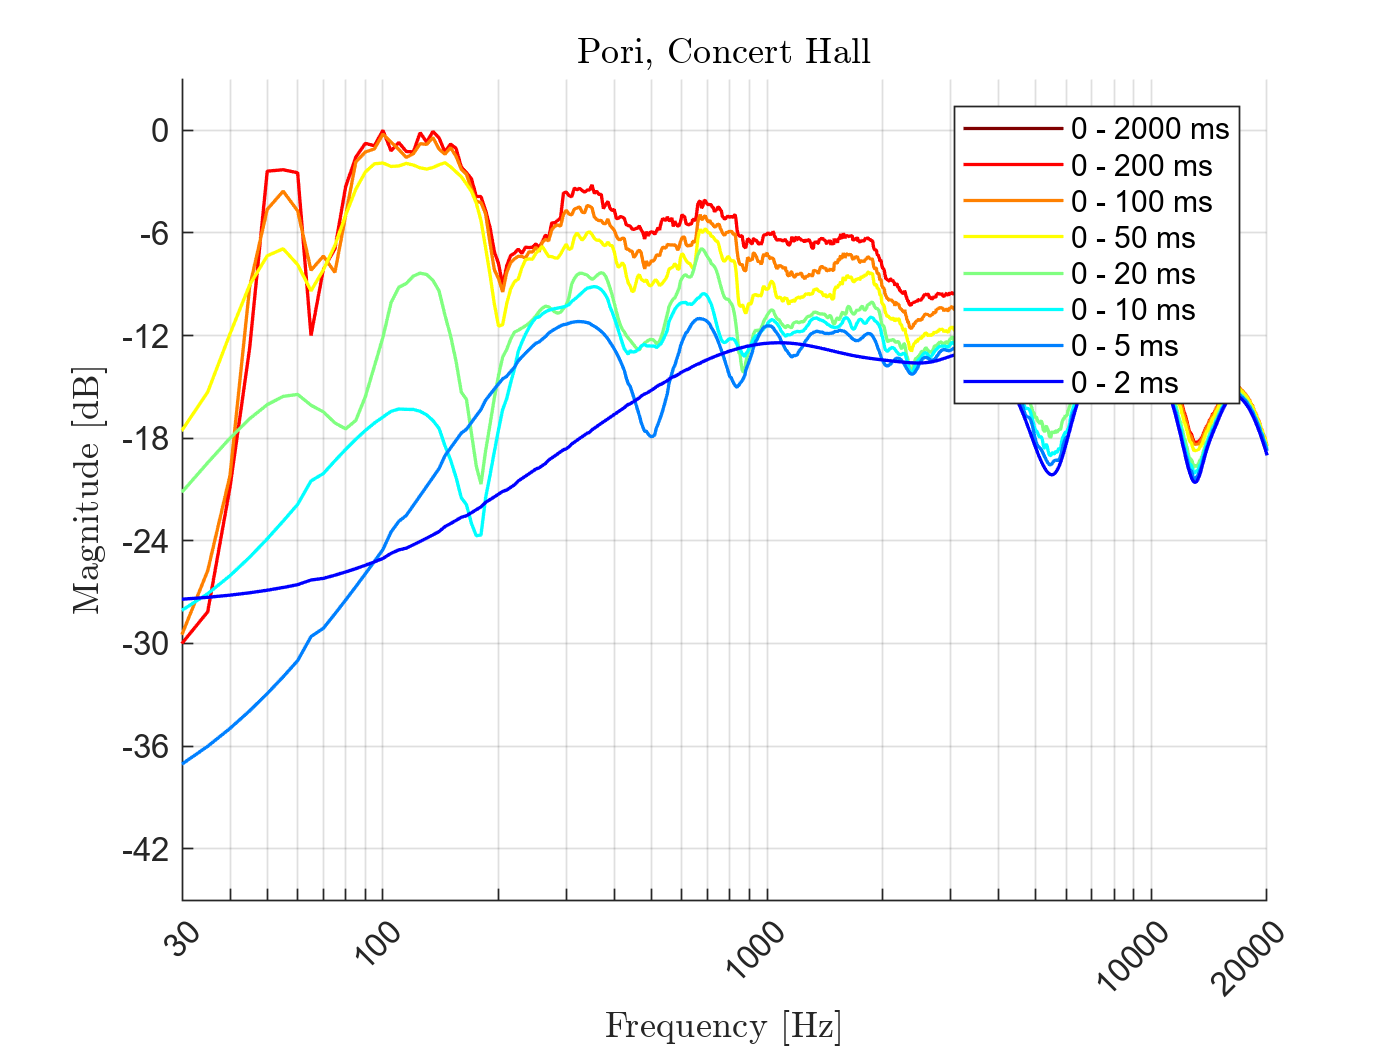

Ended time-frequency visualization in 4.7195 seconds.


timeFrequencyVisualization(P, v)

Started spatio-temporal visualization.


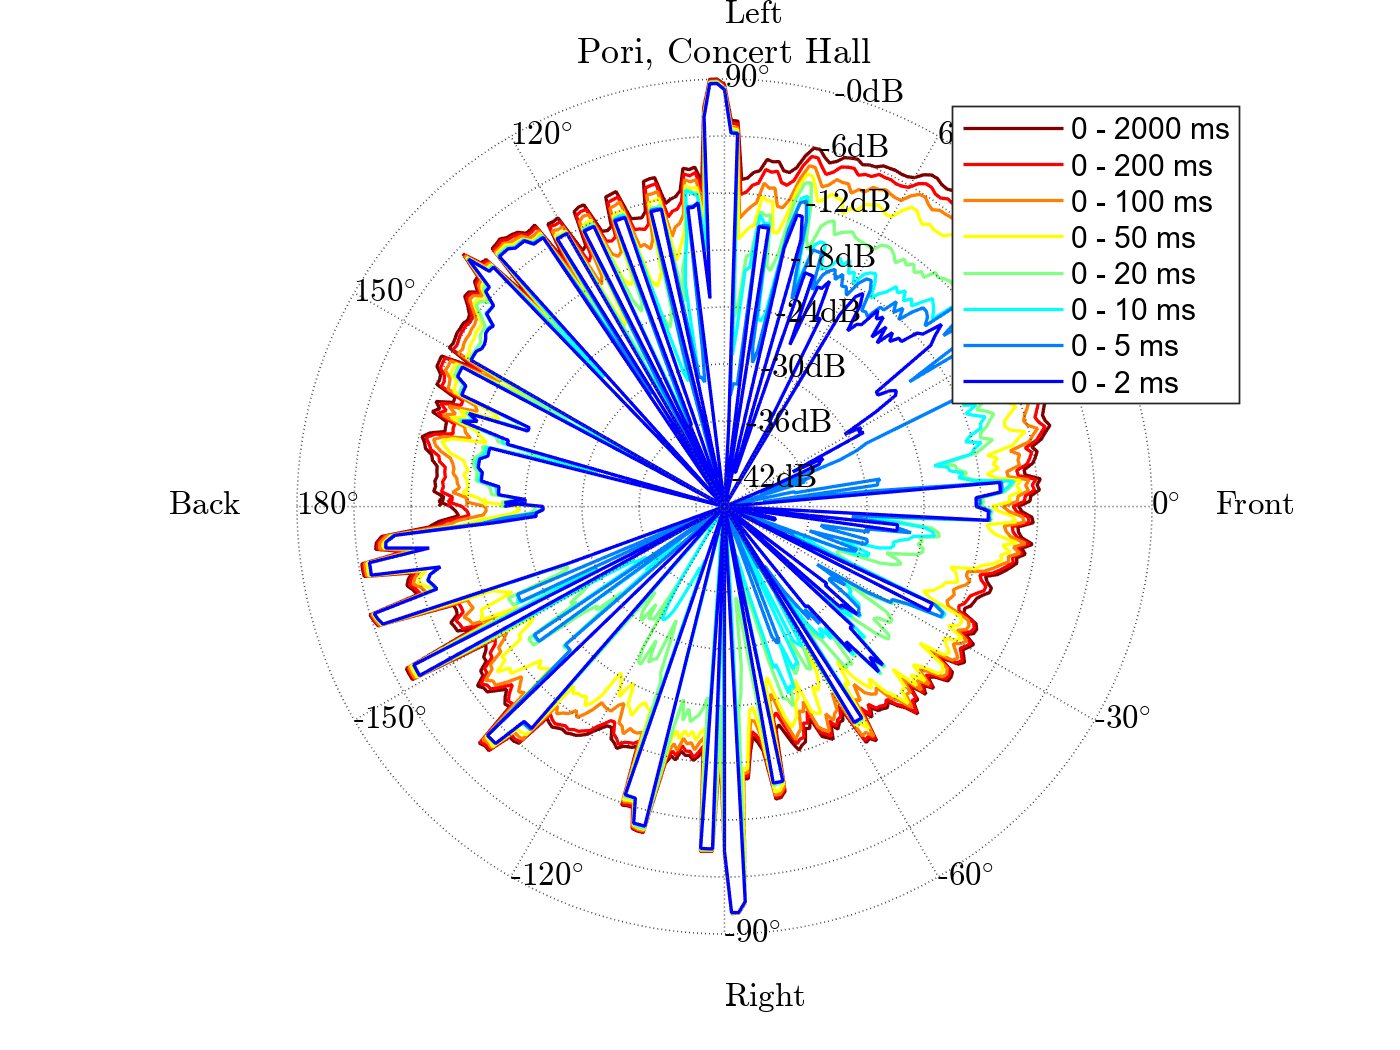

Ended spatio-temporal visualization in 1.0439 seconds.


ans = -92

v.plane = 'lateral';
spatioTemporalVisualization(P, DOA, v)

Started spatio-temporal visualization.


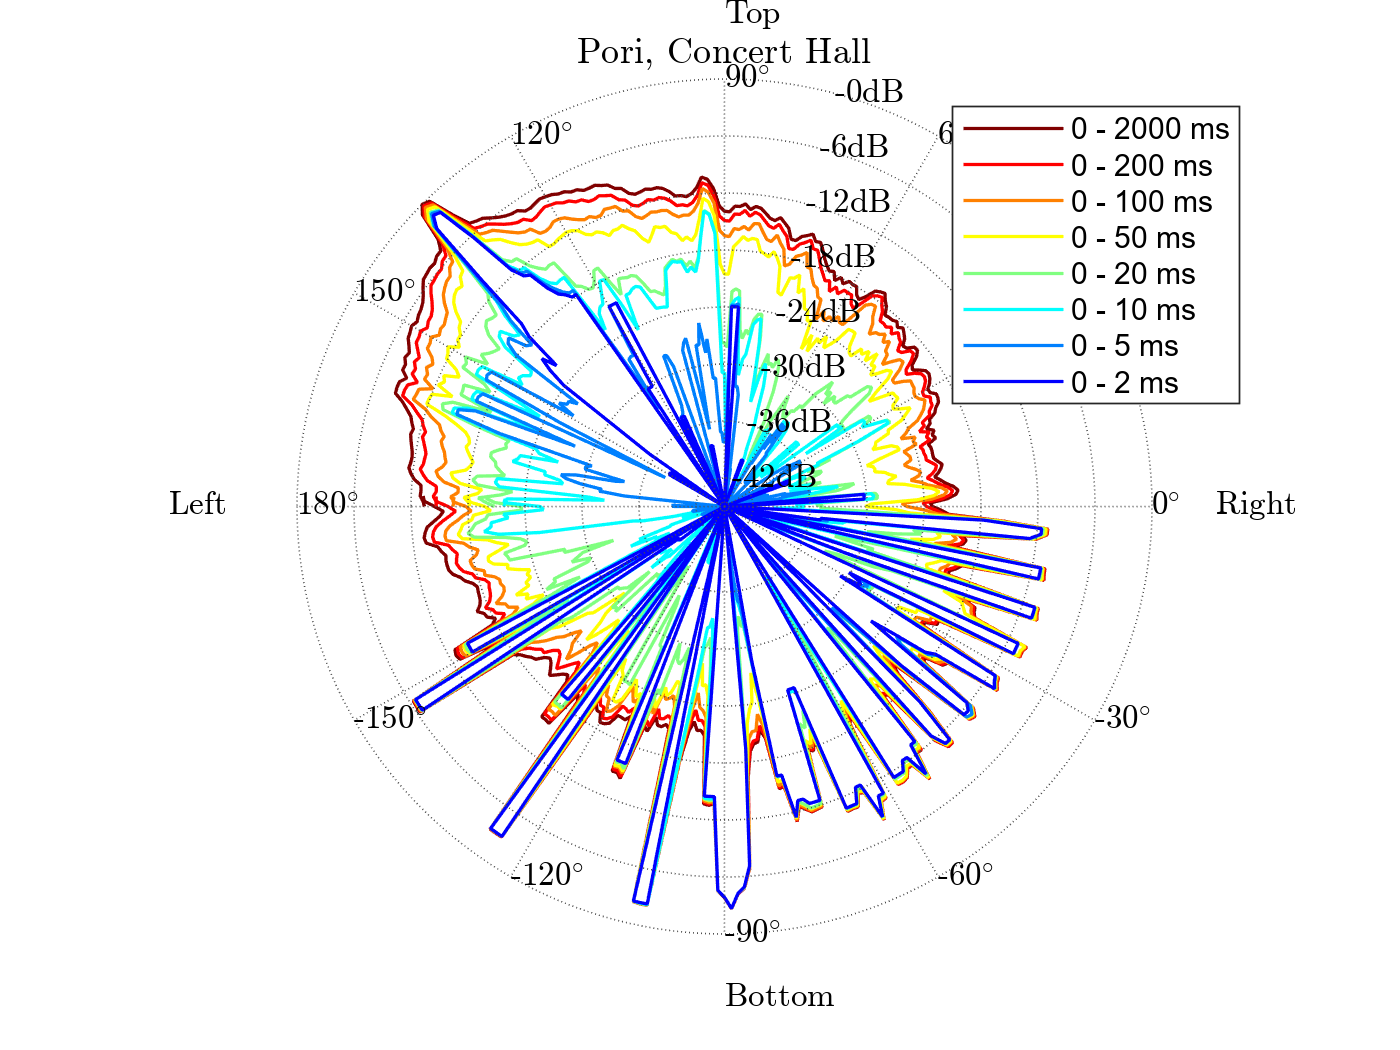

Ended spatio-temporal visualization in 0.9297 seconds.


ans = -136

v.plane = 'transverse';
spatioTemporalVisualization(P, DOA, v)

Started spatio-temporal visualization.


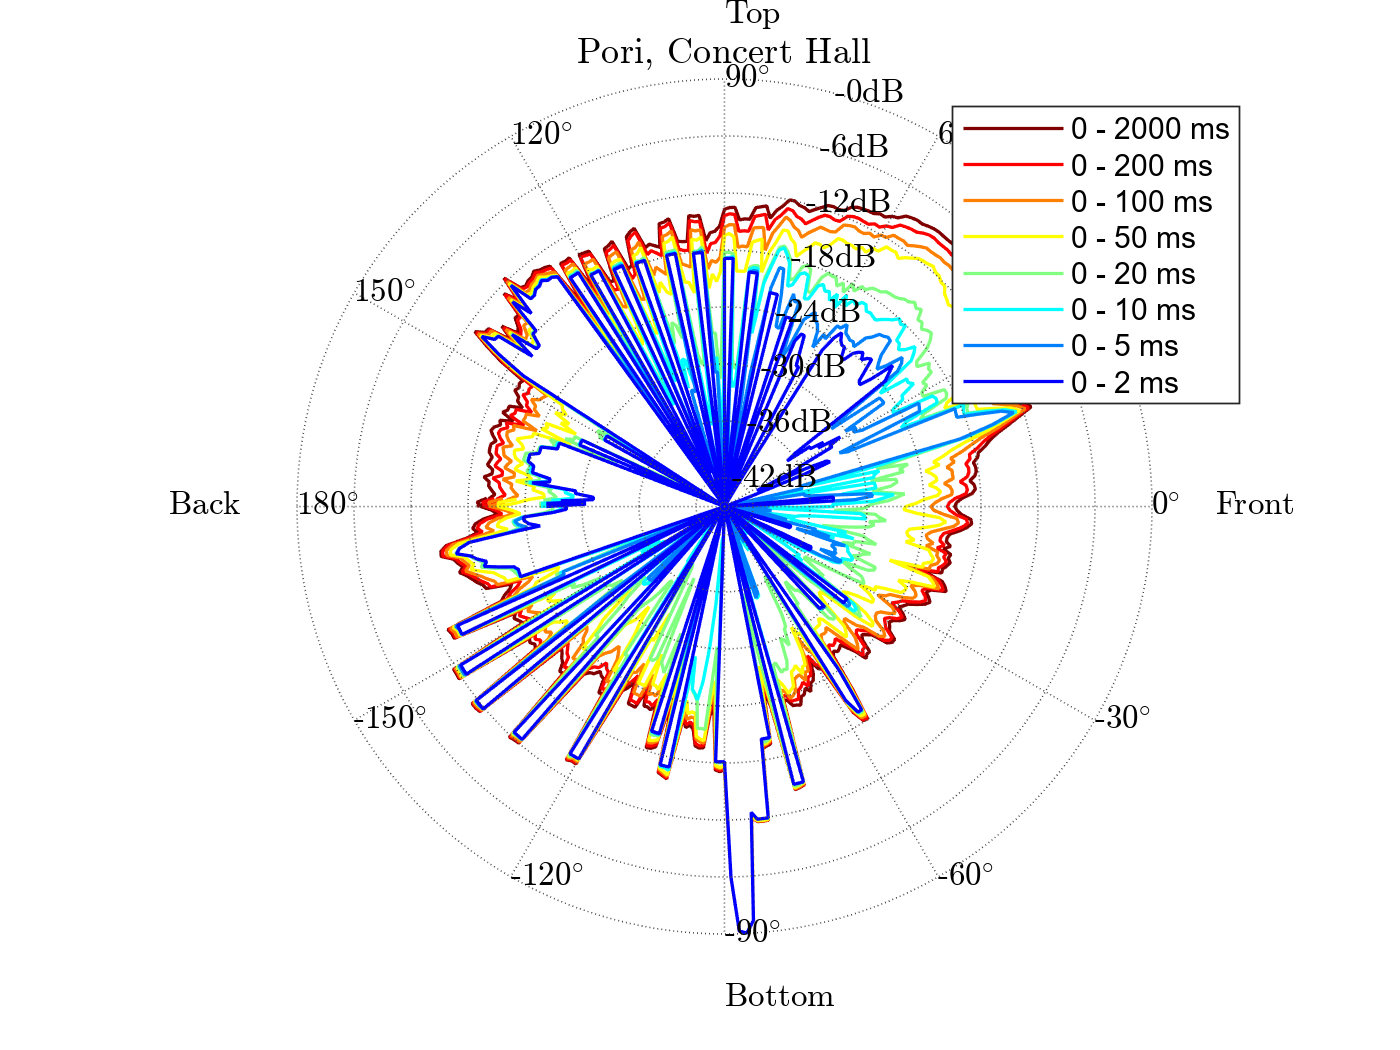

Ended spatio-temporal visualization in 0.95756 seconds.


ans = 86

v.plane = 'median';
spatioTemporalVisualization(P, DOA, v)

% Same but for speaker 2
combined_wav_files = zeros(960000, 6);

[combined_wav_files(:,1),fs] = audioread('testData\IRs_valerio\pos_0_speaker_2\ir_pos_0_speaker_2_mic1.wav');
[combined_wav_files(:,2),fs] = audioread('testData\IRs_valerio\pos_0_speaker_2\ir_pos_0_speaker_2_mic2.wav');
[combined_wav_files(:,3),fs] = audioread('testData\IRs_valerio\pos_0_speaker_2\ir_pos_0_speaker_2_mic3.wav');
[combined_wav_files(:,4),fs] = audioread('testData\IRs_valerio\pos_0_speaker_2\ir_pos_0_speaker_2_mic4.wav');
[combined_wav_files(:,5),fs] = audioread('testData\IRs_valerio\pos_0_speaker_2\ir_pos_0_speaker_2_mic5.wav');
[combined_wav_files(:,6),fs] = audioread('testData\IRs_valerio\pos_0_speaker_2\ir_pos_0_speaker_2_mic6.wav');

a = createSDMStruct('DefaultArray','GRASVI50','fs',fs,'winLen',15);

User-defined SDM Settings are used :
           fs: 192000
            c: 345
       winLen: 15
    parFrames: 8192
    showArray: 0
      micLocs: [6×3 double]



DOA{1} = SDMbf(combined_wav_files, a);

Started SDM processing
Ended SDM processing in 0.053334 seconds.



% Here we are using the pressure in the b-format as the estimate for the
% pressure in the center of the array
P{1} = combined_wav_files(:,1);

v = createVisualizationStruct('DefaultRoom','LargeRoom',...
    'name','Pori, Concert Hall','fs',fs,'t',[2 5 10 20 50 100 200 2000]);

createVisualizationStruct : User-defined visualization settings are used :
              fs: 192000
           plane: 'lateral'
             DOI: 'forward'
       plotStyle: 'line'
            name: 'Pori, Concert Hall'
             res: 1
               t: [2 5 10 20 50 100 200 2000]
          colors: [8×3 double]
       dBSpacing: 6
      DOASpacing: 30
      dBDynamics: 45
       linewidth: [1 1 1 1 1 1 1 1]
        showGrid: 1
    smoothMethod: 'average'
       smoothRes: 3



Started visualization of parameters.


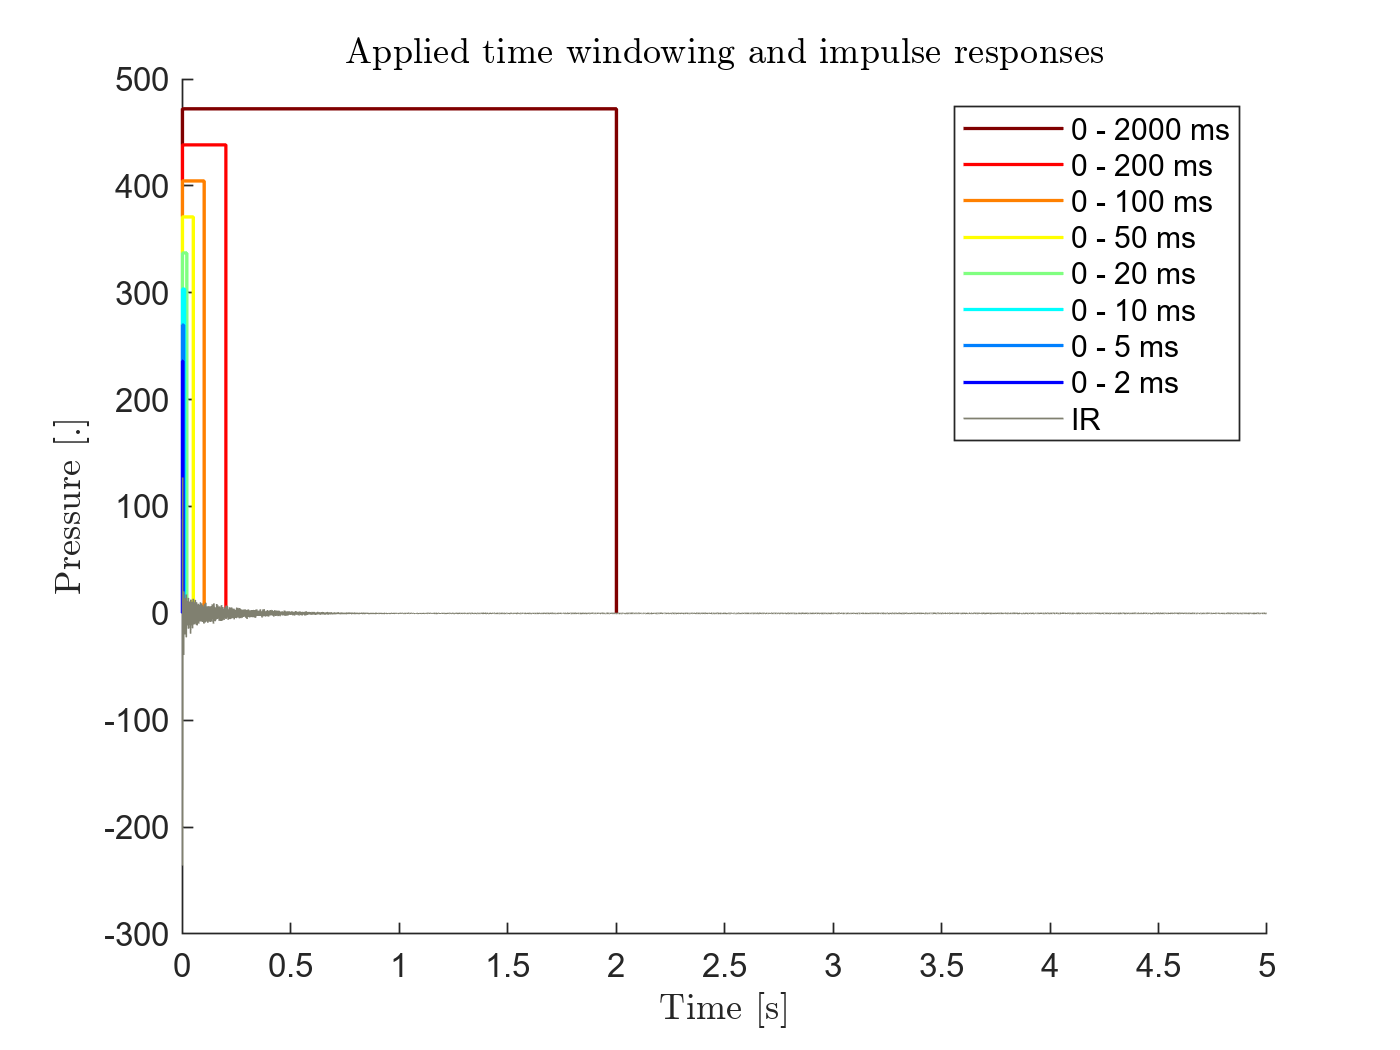

Ended visualization of parameters in 0.14171 seconds.


% For visualization purposes, set the text interpreter to latex
set(0,'DefaultTextInterpreter','latex')
parameterVisualization(P, v);


% Check hier de time windows, dunker red is the biggest windows so it takes
% the energy of the whole signal and represents it on the graphs below

Started time-frequency visualization.


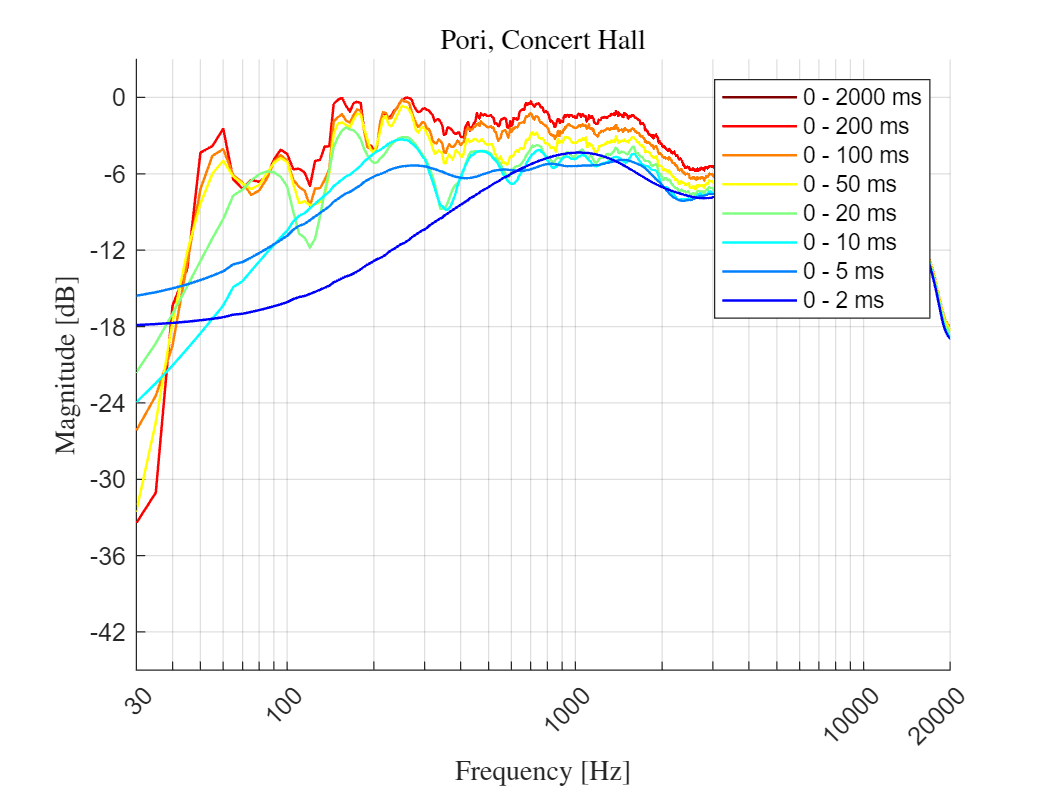

Ended time-frequency visualization in 3.0542 seconds.


timeFrequencyVisualization(P, v)

Started spatio-temporal visualization.


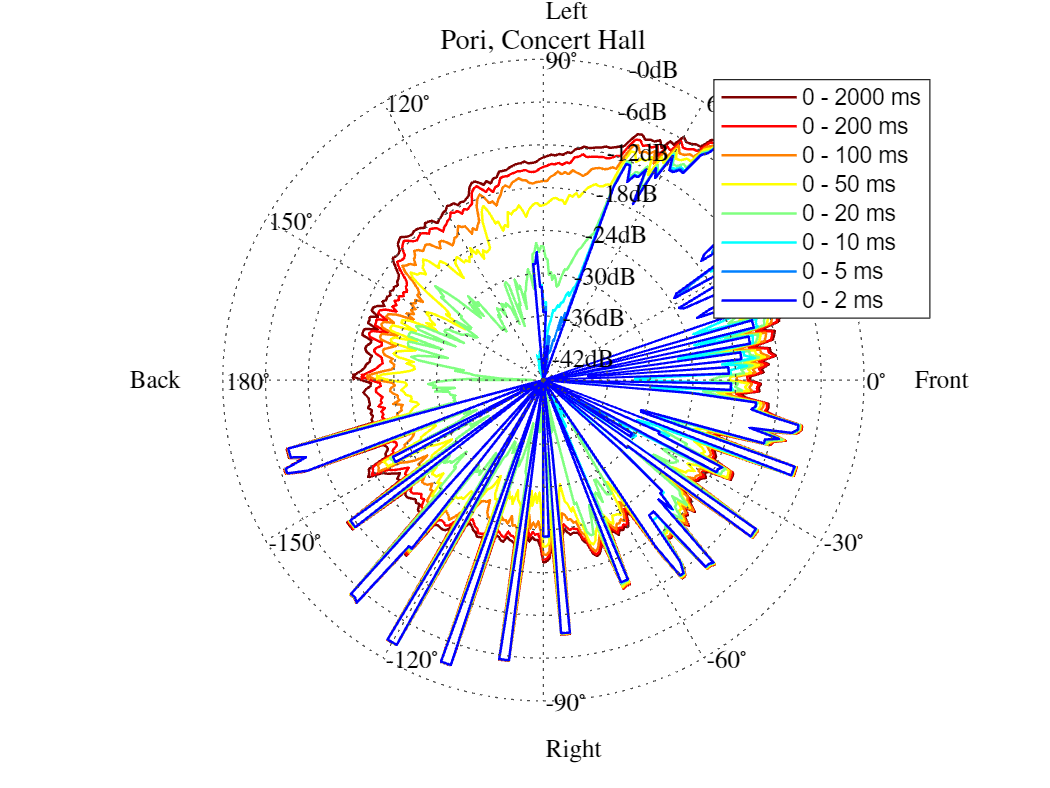

Ended spatio-temporal visualization in 0.79981 seconds.


ans = -50

v.plane = 'lateral';
spatioTemporalVisualization(P, DOA, v)

Started spatio-temporal visualization.


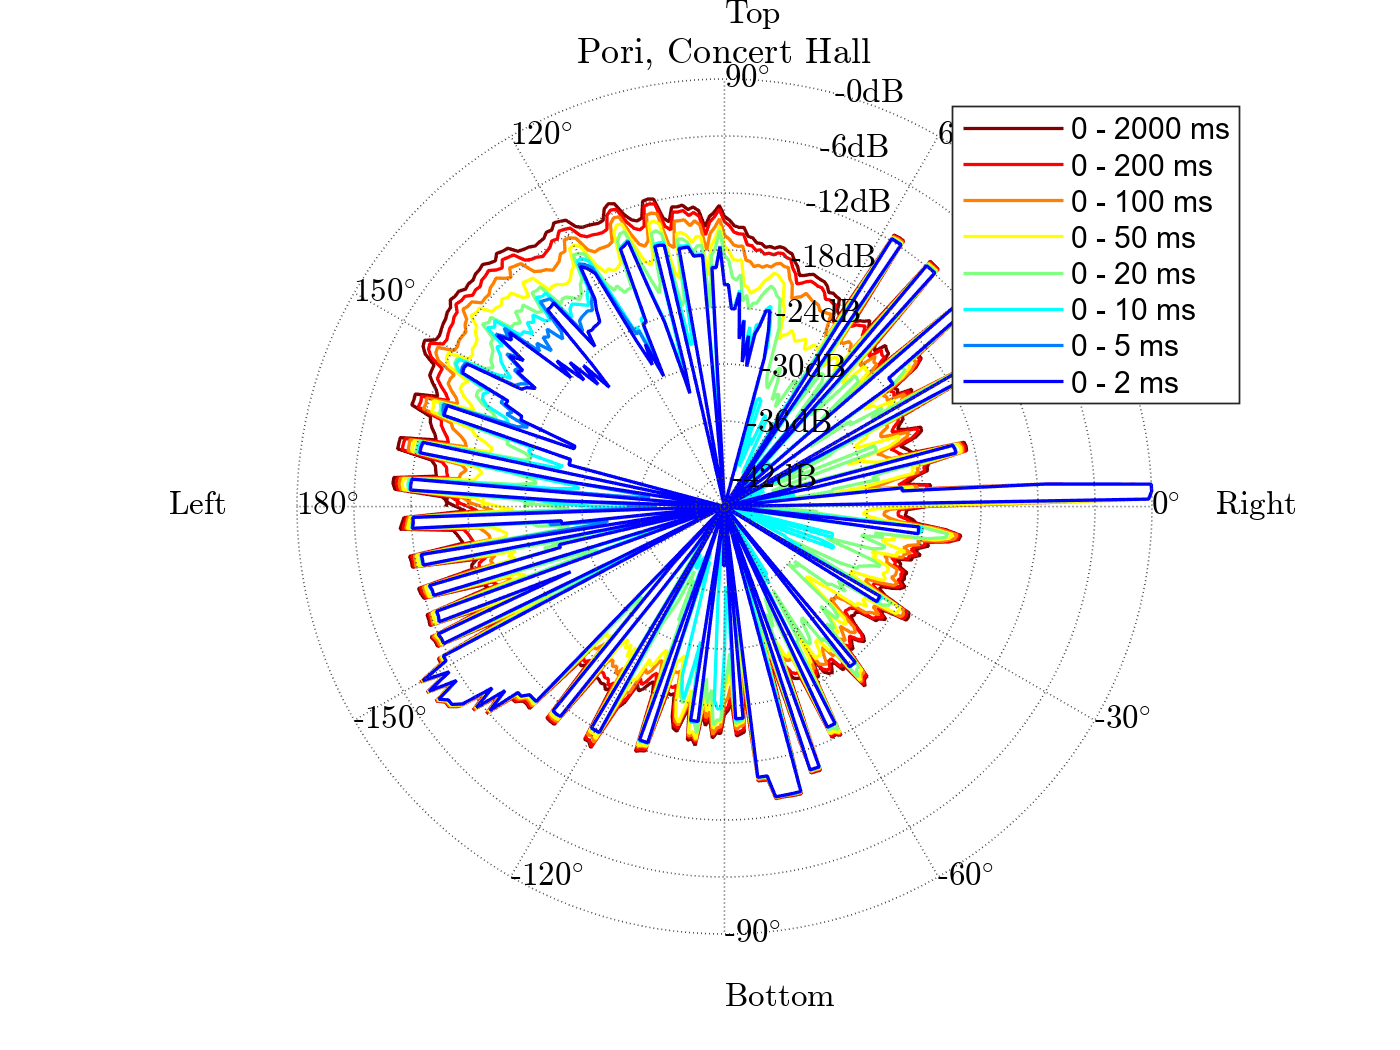

Ended spatio-temporal visualization in 0.82536 seconds.


ans = -4

v.plane = 'transverse';
spatioTemporalVisualization(P, DOA, v)

Started spatio-temporal visualization.


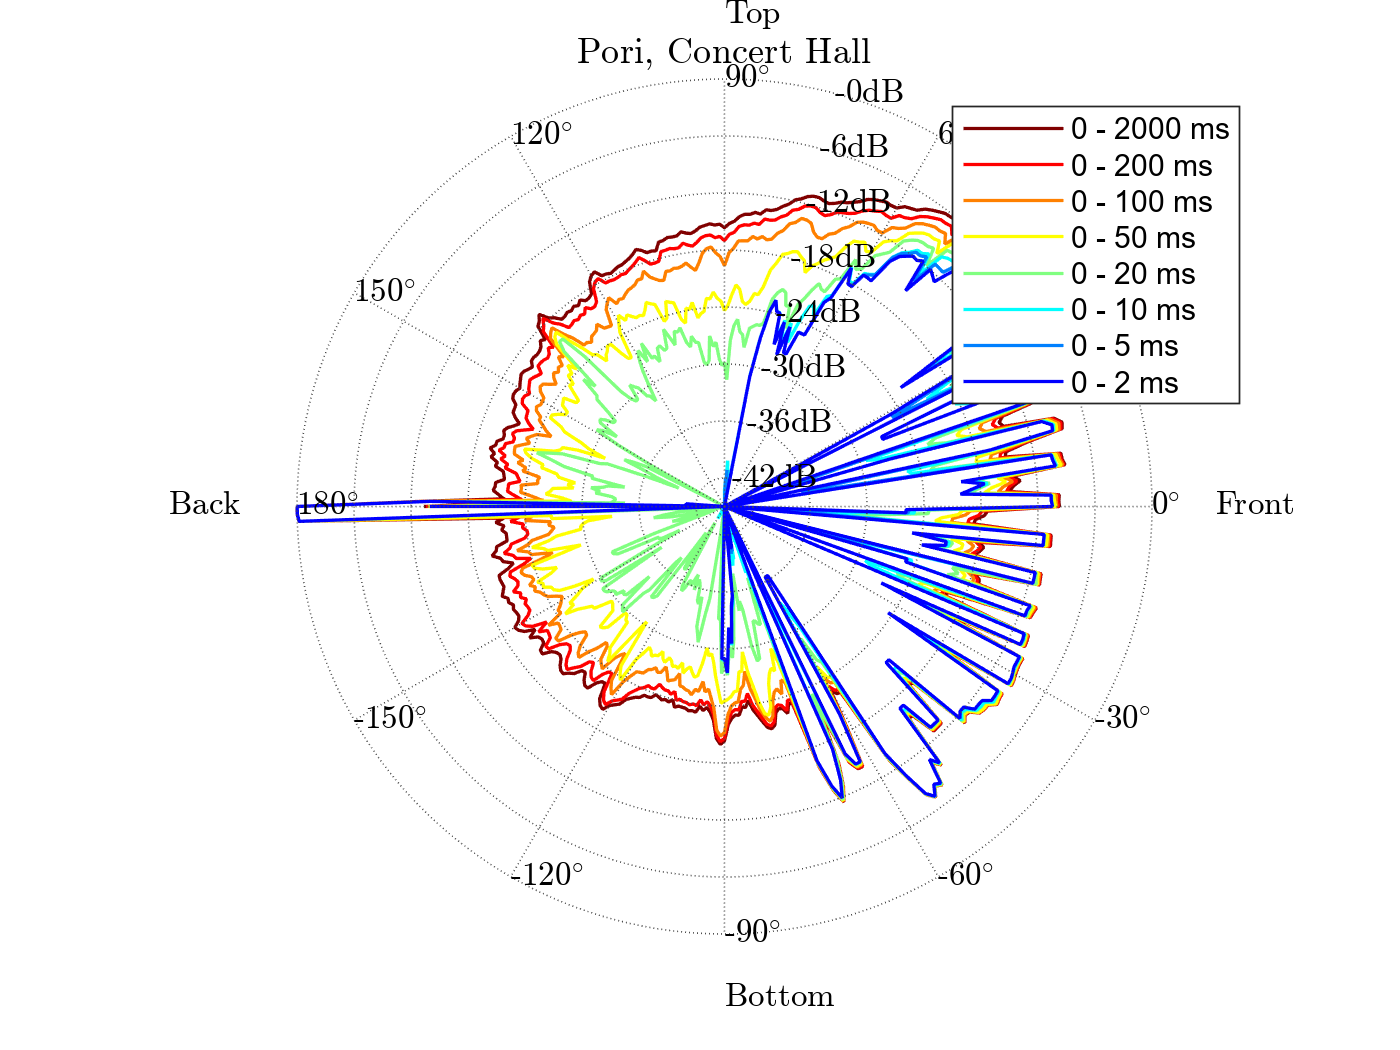

Ended spatio-temporal visualization in 0.79022 seconds.


ans = 179

v.plane = 'median';
spatioTemporalVisualization(P, DOA, v)